% Load in the test ground truth
load fastenerTestGT.mat fastenerTestGT

% Create image and box label datastores
[imds, blds] = objectDetectorTrainingData(fastenerTestGT);

% Get the list of classes
classes = categories(blds.LabelData{1,2});

% Create a combined datastore
testData = combine(imds, blds);

% Load original fastener detector from Course 2
load fastenerTinyYolo4Detector.mat detector

% Load new fastener detector with augmentation
load fastenerTinyYolo4DetectorAug.mat detectorAug

IoU = 0.5;

% Set up range of threshold values
thresholds = 0.05:0.05:0.9;

% Initialize matrices to store the AP values
apMatrixOriginal = zeros(4, length(thresholds));
apMatrixAug = zeros(4, length(thresholds));

% Create waitbar to see progress
f = waitbar(0, "Running detectors and evaluating results");

% Calculate average precision for each class and threshold
for ii = 1:length(thresholds)
    testResultsOriginal = detect(detector, testData, "Threshold", thresholds(ii));
    testResultsAug = detect(detectorAug, testData, "Threshold", thresholds(ii));
    apMatrixOriginal(:,ii) = evaluateDetectionPrecision(testResultsOriginal, testData, IoU);
    apMatrixAug(:,ii) = evaluateDetectionPrecision(testResultsAug, testData, IoU);
    waitbar(ii/length(thresholds), f, "Running detectors and evaluating results")
end
close(f)

mAPOriginal = mean(apMatrixOriginal);
mAPAug = mean(apMatrixAug);

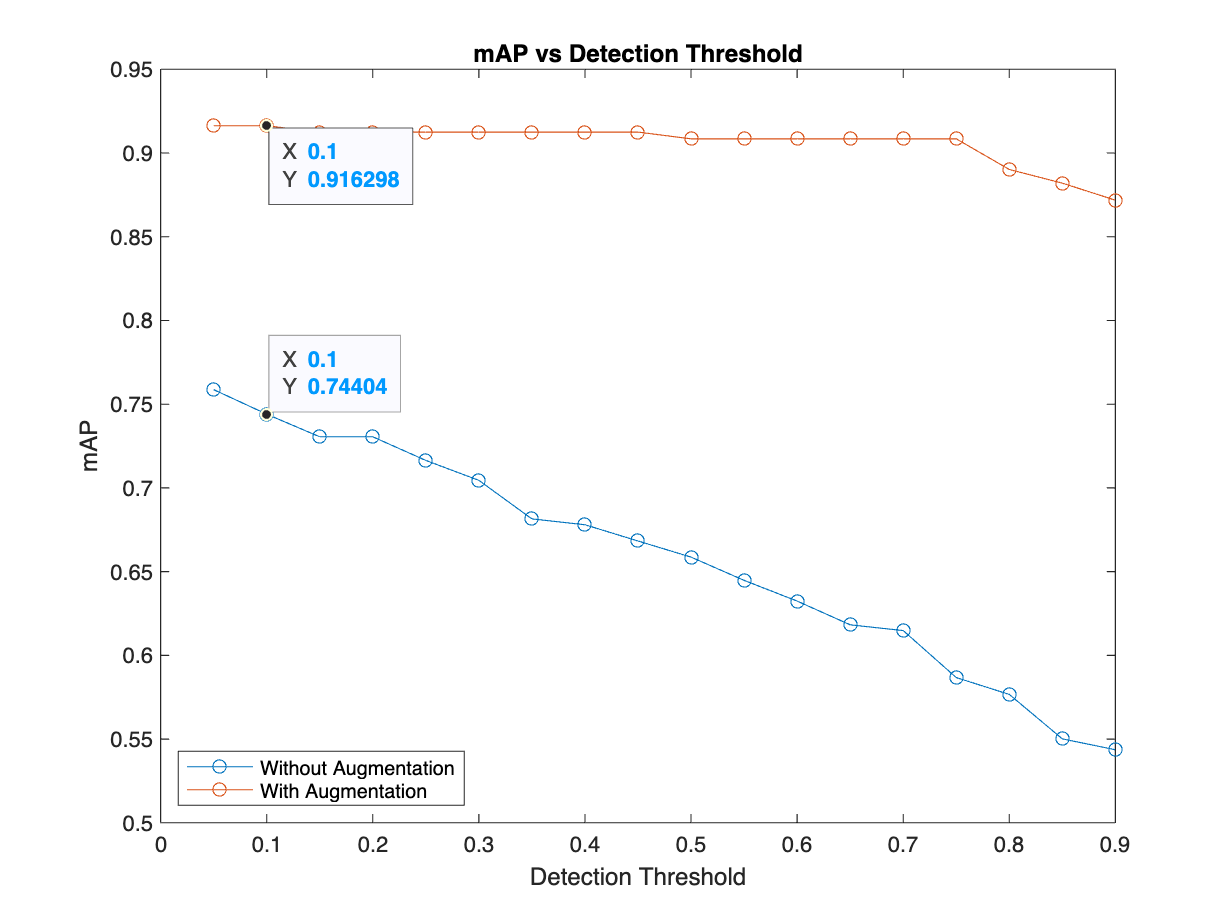

plot(thresholds, mAPOriginal, "-o")
hold on
plot(thresholds, mAPAug, "-o")
hold off
xlabel("Detection Threshold")
ylabel("mAP")
legend(["Without Augmentation", "With Augmentation"], "Location","southwest")
title("mAP vs Detection Threshold")

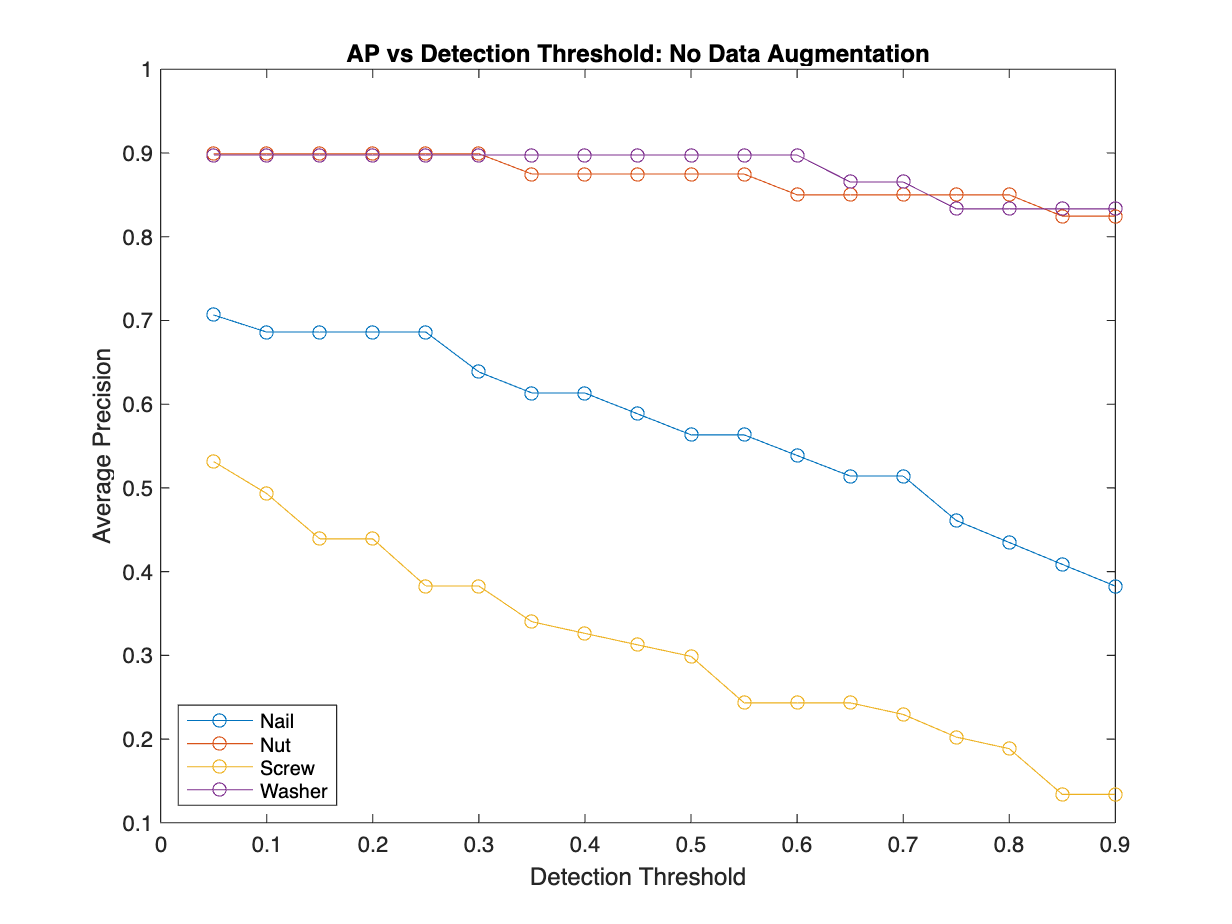

% Plot the results for the original detector
plot(thresholds,apMatrixOriginal,"-o")
xlabel("Detection Threshold")
ylim([0.1 1])
ylabel("Average Precision")
legend(["Nail", "Nut", "Screw", "Washer"], "Location","southwest")
title("AP vs Detection Threshold: No Data Augmentation")

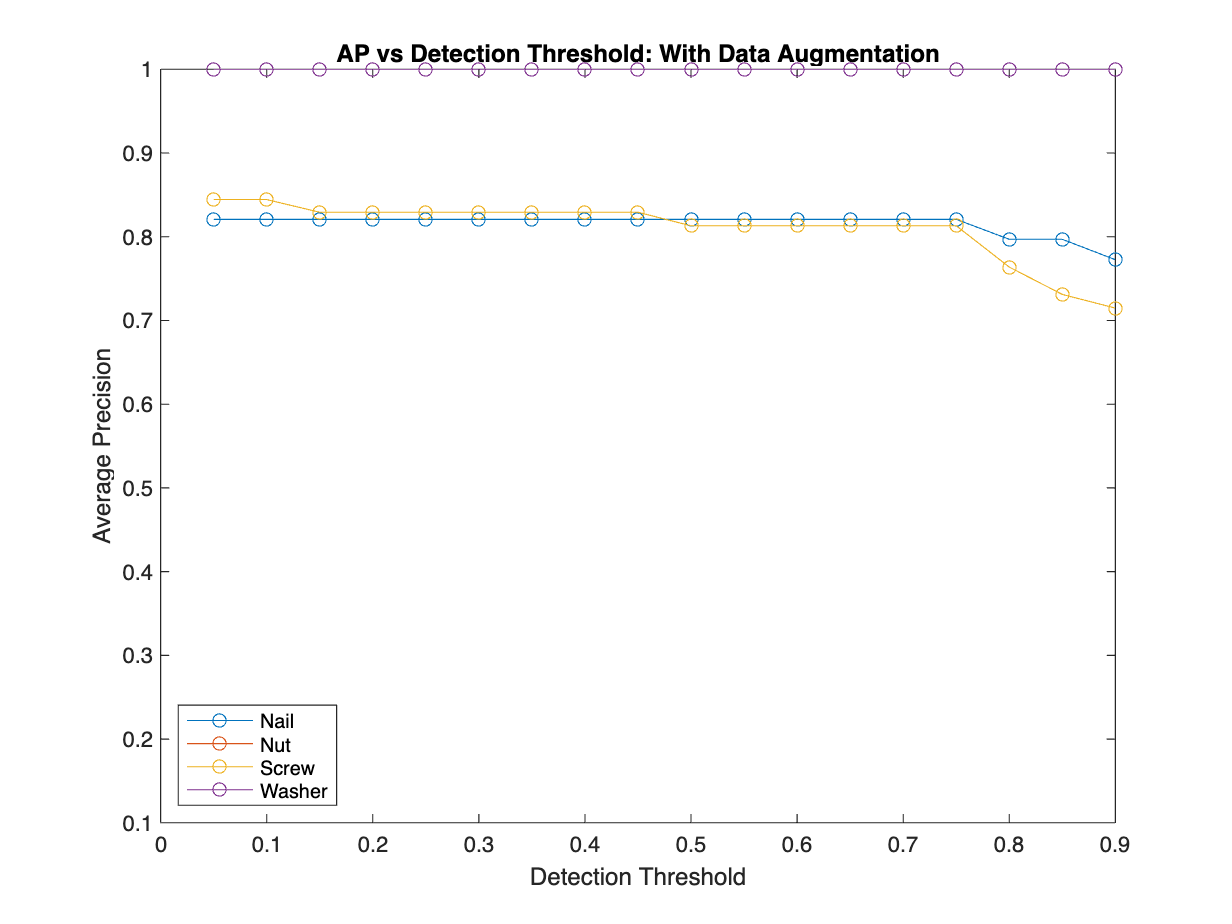

% Plot the results for the new detector
plot(thresholds,apMatrixAug,"-o")
xlabel("Detection Threshold")
ylim([0.1,1])
ylabel("Average Precision")
legend(classes, "Location","southwest")
title("AP vs Detection Threshold: With Data Augmentation")